rootorigin ='C:\Users\Lyriss\Desktop\nwhales\output3\';
rootsave ='C:\Users\Lyriss\Desktop\nwhales\temp\';
addpath(rootorigin);
addpath(rootsave);
for i=1:1:81
for n=1:1:81
%open first file
disp(i);

     1



disp(n);

     3



filename= sprintf('chunk%d.wav',i);
fullname = strcat(rootorigin, filename);
[audio1, fs1] = audioread(fullname);
%open 2nd file
filename2= sprintf('chunk%d.wav',n);
fullname2 = strcat(rootorigin, filename2);
[audio2, fs2] = audioread(fullname2);
% get both len 
len_audio1 = numel(audio1);
len_audio2 = numel(audio2);

%len fix
if len_audio1>len_audio2
    audio1=audio1(1:len_audio2);
else 
    audio2=audio2(1:len_audio1);
end
%spectrograms 
% subplot(4,1,1);
% spectrogram(audio1, hann(256, "periodic"), 250, 256, fs1,'yaxis');
% title('Spectrogram for Audio File 1');
% subplot(4,1,2);
% spectrogram(audio2, hann(256, "periodic"), 250, 256, fs2,'yaxis');
% title('Spectrogram for Audio File 2');
%stft
stft1 = stft(audio1, fs1, Window=hann(256,"periodic"),OverlapLength=250,FFTLength=256);
stft2 = stft(audio2, fs2, Window=hann(256,"periodic"),OverlapLength=250,FFTLength=256);
%crop points
dAt = floor(size(stft1, 1) / 2);
dAt1 = floor(size(stft1,2)/3);
dAt2 = dAt1+dAt1;
%mix by freq
mod_stft1_stft2 = [stft2(1:dAt, :);stft1(dAt+1:end, :)];
modified1 = real(istft(mod_stft1_stft2, fs1, Window=hann(256, 'periodic'), OverlapLength=250, FFTLength=256));
%mix by time
% MY mod_stft1_stft2T=[stft1( : , 1:dAt1); stft2( : , dAt1+1:dAt2); stft1( : , dAt2+1:end)];
mod_stft1_stft2T = [stft1(:, 1:dAt1), stft2(:, dAt1+1:dAt2), stft1(:, dAt2+1:end)];
modified2 = real(istft(mod_stft1_stft2T, fs1, Window=hann(256, 'periodic'), OverlapLength=250, FFTLength=256));
%save for freq
filenameend=sprintf('freq_chunk_%d_%d.wav', i,n);
fullfilenameend=strcat(rootsave,filenameend);
audiowrite(fullfilenameend, modified1, fs1);

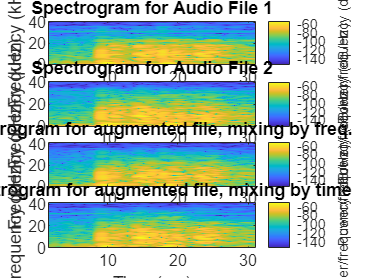

%save for time
filenameend=sprintf('time_chunk_%d_%d.wav', i,n);
fullfilenameend=strcat(rootsave,filenameend);
audiowrite(fullfilenameend, modified2, fs1);
%spectrograms 
% subplot(4,1,3)
% spectrogram(modified1, hann(256, "periodic"), 250, 256, fs1,'yaxis');
% title('Spectrogram for augmented file, mixing by freq.');
% subplot(4,1,4)
% spectrogram(modified2, hann(256, "periodic"), 250, 256, fs1,'yaxis');
% title('Spectrogram for augmented file, mixing by time');

end
end